# HW1

## PROBLEM 1

## a. Plot

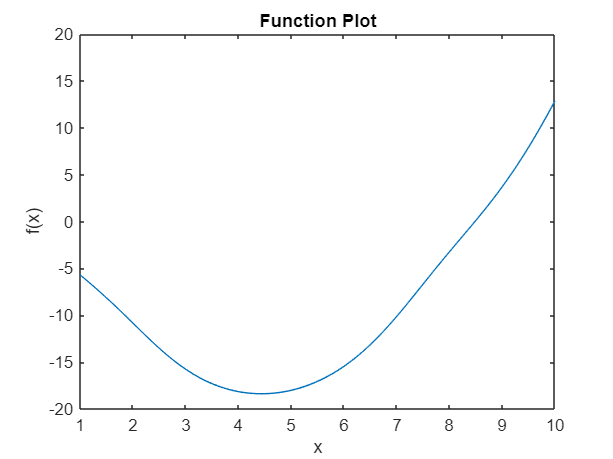

syms x;
f = x.^2 - 9*x + exp(sin(x)) + log(x);
x_val = linspace(1, 10);
f_numerical = matlabFunction(f);
plot(x_val, f_numerical(x_val));
xlim([1 10]);
ylim([-20 20]);
xticks(1:10);
xlabel("x");
ylabel("f(x)");
title("Function Plot");

## b. Golden Search

interval_length = zeros(4, 15);
a1 = 10 * rand;
b1 = a1 + (10 - a1) * rand;
phi = 0.5 * (1 - ((b1 - a1) / 9));
for i = 1:15
    value_a1 = f_numerical(a1);
    value_b1 = f_numerical(b1);
    if value_b1 > value_a1
        interval1 = [1, b1];
    else
        interval1 = [a1, 10];
    end
    interval_length(1, i) = interval1(2) - interval1(1);
    phi = (3 - sqrt(5)) / 2;
    a1 = 1 + phi * (b1 - 1);
    b1 = 1 + (1 - phi) * (b1 - 1);
    fprintf('Iteration %d: f(a1) = %.6f, f(b1) = %.6f, Uncertainty Interval: [%.6f, %.6f]\n', i, value_a1, value_b1, interval1(1), interval1(2));
end

Iteration 1: f(a1) = -5.544185, f(b1) = -0.520754, Uncertainty Interval: [1.000000, 8.406057]
Iteration 2: f(a1) = -17.926768, f(b1) = -16.848286, Uncertainty Interval: [1.000000, 5.577195]
Iteration 3: f(a1) = -14.703694, f(b1) = -17.926768, Uncertainty Interval: [2.748333, 10.000000]
Iteration 4: f(a1) = -11.269756, f(b1) = -14.703694, Uncertainty Interval: [2.080529, 10.000000]
Iteration 5: f(a1) = -9.011625, f(b1) = -11.269756, Uncertainty Interval: [1.667804, 10.000000]
Iteration 6: f(a1) = -7.688612, f(b1) = -9.011625, Uncertainty Interval: [1.412725, 10.000000]
Iteration 7: f(a1) = -6.906092, f(b1) = -7.688612, Uncertainty Interval: [1.255078, 10.000000]
Iteration 8: f(a1) = -6.433362, f(b1) = -6.906092, Uncertainty Interval: [1.157647, 10.000000]
Iteration 9: f(a1) = -6.144328, f(b1) = -6.433362, Uncertainty Interval: [1.097431, 10.000000]
Iteration 10: f(a1) = -5.966620, f(b1) = -6.144328, Uncertainty Interval: [1.060216, 10.000000]
Iteration 11: f(a1) = -5.857079, f(b1) = -5.

## c. Fibonacci Method

a1 = 10 * rand;
b1 = a1 + (10 - a1) * rand;
phi = 0.5 * (1 - ((b1 - a1) / 9));
for i = 1:15
    value_a1 = f_numerical(a1);
    value_b1 = f_numerical(b1);
    if value_b1 > value_a1
        interval2 = [1, b1];
    else
        interval2 = [a1, 10];
    end
    interval_length(2, i) = interval2(2) - interval2(1);
    phi = 1 - (fibonacci(16-i) / fibonacci(17-i));
    a1 = 1 + phi * (b1 - 1);
    b1 = 1 + (1 - phi) * (b1 - 1);
    fprintf('Iteration %d: f(a1) = %.6f, f(b1) = %.6f, Uncertainty Interval: [%.6f, %.6f]\n', i, value_a1, value_b1, interval2(1), interval2(2));
end

Iteration 1: f(a1) = -10.463783, f(b1) = -3.799112, Uncertainty Interval: [1.000000, 7.915983]
Iteration 2: f(a1) = -17.601725, f(b1) = -17.558557, Uncertainty Interval: [1.000000, 5.274316]
Iteration 3: f(a1) = -14.167165, f(b1) = -17.601725, Uncertainty Interval: [2.632648, 10.000000]
Iteration 4: f(a1) = -10.874180, f(b1) = -14.167165, Uncertainty Interval: [2.009019, 10.000000]
Iteration 5: f(a1) = -8.777338, f(b1) = -10.874180, Uncertainty Interval: [1.623630, 10.000000]
Iteration 6: f(a1) = -7.551127, f(b1) = -8.777338, Uncertainty Interval: [1.385389, 10.000000]
Iteration 7: f(a1) = -6.823877, f(b1) = -7.551127, Uncertainty Interval: [1.238241, 10.000000]
Iteration 8: f(a1) = -6.382819, f(b1) = -6.823877, Uncertainty Interval: [1.147149, 10.000000]
Iteration 9: f(a1) = -6.114013, f(b1) = -6.382819, Uncertainty Interval: [1.091092, 10.000000]
Iteration 10: f(a1) = -5.946796, f(b1) = -6.114013, Uncertainty Interval: [1.056057, 10.000000]
Iteration 11: f(a1) = -5.846706, f(b1) = -5

## d. Bisection Method

a0 = x_val(1);
b0 = x_val(end);
x0 = (b0 + a0) / 2;
df = matlabFunction(diff(f, 1));
for i = 1:15
    df_val = df(x0);
    if df_val > 0
        interval3 = [a0, x0];
    elseif df_val < 0
        interval3 = [x0, b0];
    interval_length(3, i) = interval3(2) - interval3(1);
    else
        fprintf("Iteration %d: f'(x0) = %.6f, Minimizer = %.6f", i, df_val, x0);
        break;
    end
    a0 = interval3(1);
    b0 = interval3(end);
    x0 = (b0 + a0) / 2;
    fprintf("Iteration %d: f'(x0) = %.6f, Uncertainty Interval: [%.6f, %.6f]\n", i, df_val, interval3(1), interval3(2));
end

Iteration 1: f'(x0) = 2.531789, Uncertainty Interval: [1.000000, 5.500000]
Iteration 2: f'(x0) = -3.084492, Uncertainty Interval: [3.250000, 5.500000]
Iteration 3: f'(x0) = -0.150268, Uncertainty Interval: [4.375000, 5.500000]
Iteration 4: f'(x0) = 1.161746, Uncertainty Interval: [4.375000, 4.937500]
Iteration 5: f'(x0) = 0.506591, Uncertainty Interval: [4.375000, 4.656250]
Iteration 6: f'(x0) = 0.179383, Uncertainty Interval: [4.375000, 4.515625]
Iteration 7: f'(x0) = 0.014989, Uncertainty Interval: [4.375000, 4.445312]
Iteration 8: f'(x0) = -0.067516, Uncertainty Interval: [4.410156, 4.445312]
Iteration 9: f'(x0) = -0.026234, Uncertainty Interval: [4.427734, 4.445312]
Iteration 10: f'(x0) = -0.005616, Uncertainty Interval: [4.436523, 4.445312]
Iteration 11: f'(x0) = 0.004689, Uncertainty Interval: [4.436523, 4.440918]
Iteration 12: f'(x0) = -0.000463, Uncertainty Interval: [4.438721, 4.440918]
Iteration 13: f'(x0) = 0.002113, Uncertainty Interval: [4.438721, 4.439819]
Iteration 14: f

## e. Newton's Method

x_k = 7;
df = matlabFunction(diff(f));
ddf = matlabFunction(diff(f, 2));
for i = 1:15
    x_k = x_k - df(x_k) / ddf(x_k);
    x = x_k - df(x_k) / ddf(x_k);
    interval_length(4, i) = abs(x - x_k);
    if df(x) == 0
        fprintf("Iteration %d: Minimizer: %.15f\n", i, x);
    end
    fprintf("Iteration %d: Value of x: %.15f\n", i, x);

end

Iteration 1: Value of x: 4.329200051725151
Iteration 2: Value of x: 4.438326488104302
Iteration 3: Value of x: 4.438918199685141
Iteration 4: Value of x: 4.438918213100447
Iteration 5: Value of x: 4.438918213100448
Iteration 6: Value of x: 4.438918213100447
Iteration 7: Value of x: 4.438918213100448
Iteration 8: Value of x: 4.438918213100447
Iteration 9: Value of x: 4.438918213100448
Iteration 10: Value of x: 4.438918213100447
Iteration 11: Value of x: 4.438918213100448
Iteration 12: Value of x: 4.438918213100447
Iteration 13: Value of x: 4.438918213100448
Iteration 14: Value of x: 4.438918213100447
Iteration 15: Value of x: 4.438918213100448


## f. Plot of the interval lengths

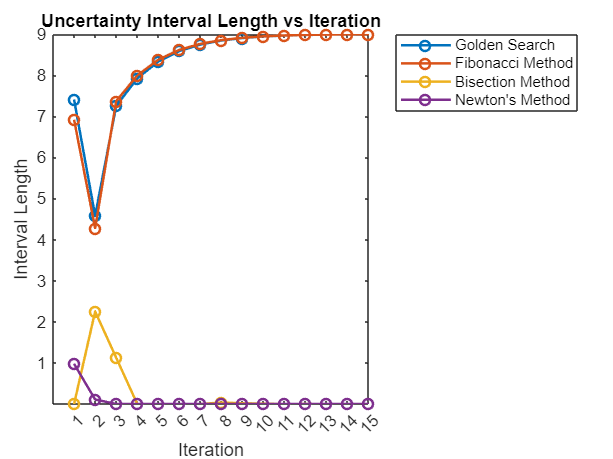

figure;
plot(1:15, interval_length', '-o', 'LineWidth', 1.5);
xticks(1:15);
yticks(1:10);
xlabel("Iteration");
ylabel("Interval Length");
title("Uncertainty Interval Length vs Iteration");
legend("Golden Search", "Fibonacci Method", "Bisection Method", "Newton's Method", 'Location','northeastoutside');

## g. Table

iterations = [1, 5, 10, 15];
methods = ["Golden Search", "Fibonacci Method", "Bisection Method", "Newton's Method"];
T = array2table(interval_length(:, iterations), 'VariableNames', "iteration= "+string(iterations), 'RowNames', methods);
disp(T);

                          iteration= 1           iteration= 5           iteration= 10           iteration= 15    
                        _________________    ____________________    ____________________    ____________________

    Golden Search        7.40605683925108        8.33219627139932        8.93978417535639        8.99457034247906
    Fibonacci Method     6.91598307959642        8.37637032007692        8.94394339955748        8.99299292494468
    Bisection Method                    0                       0            0.0087890625                       0
    Newton's Method     0.976733519382701    8.88178419700125e-16    8.88178419700125e-16    8.88178419700125e-16



## PROBLEM 2

## **Secant Method**

g = @(x) x*tan(3*x) + 2 * x.^3 + 1;
x_k0 = 0;
x_k = 1;
epsilon = 10^-5;
while abs(x_k - x_k0) >= epsilon
    x = x_k - (x_k - x_k0) * g(x_k) / (g(x_k) - g(x_k0));
    x_k0 = x_k;
    x_k = x;
end
fprintf("Root of g: %d\nValue of g at root x: %d", x, g(x));

Root of g: 6.559373e-01
Value of g at root x: 7.639287e-10